# **Classifiers (Attemps)**

# Preparation of the dataset

We first apply some transformations rule on the data to make them normally distributed.

clear all
clc
load('TrainNeeds.mat');
load('TestNeeds.mat');
load('Needs')

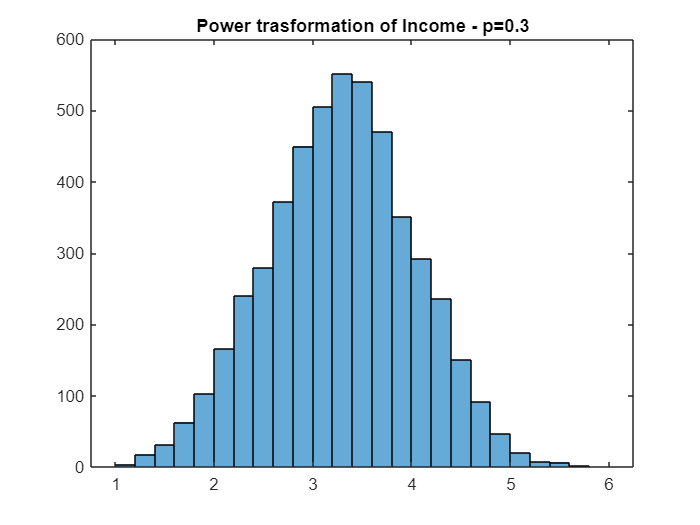

Data = Needs; % renaming (we'll likely manipulate this matrix, but we don't touch the original matrix)

% Power trasformation of Income (p=0.3)
p = 0.3;
figure
histogram(Data.Income.^p);
title('Power trasformation of Income - p=0.3')

PowerIncome=Data.Income.^p;

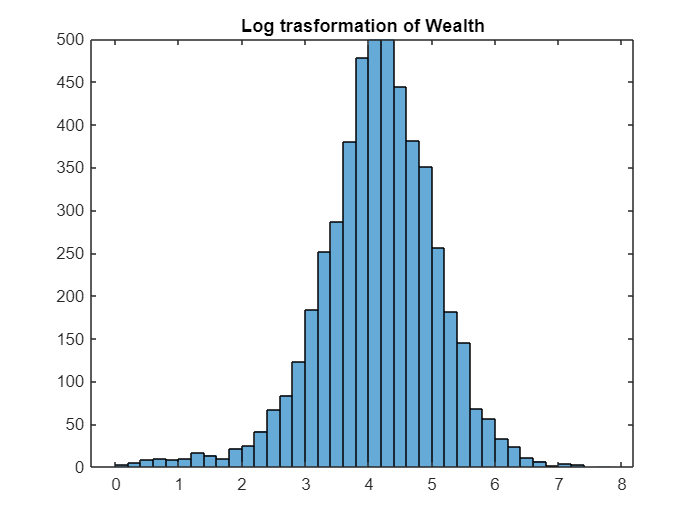

% Log trasformation of Wealth
figure
histogram(log(Data.Wealth))
title('Log trasformation of Wealth')

logWealth = log(Data.Wealth);

% for reproducibility
rng('default');

We rescale the data and separate the training and test set.

% for reproducibility
rng('default');

% Creation of dataset following R hints 
DataSmall = [rescale(Needs.Age) rescale(Needs.FamilyMembers) rescale(Needs.FinancialEducation)...
     rescale(PowerIncome) rescale(logWealth)];

Datanames= {'Age', 'Family', 'FinEdu', 'Income', 'Wealth'};

DataTrain=DataSmall(TrainNeeds1.Numberinizialdataset, :);
DataTest=DataSmall(TestNeeds.Numberinizialdataset, :);


% Final Train set table
TrainTable = table(DataTrain(:,1),DataTrain(:,2),DataTrain(:,3),DataTrain(:,4),DataTrain(:,5),'VariableNames',Datanames)% Final Test set table

TrainTable = 4000×5 table
      Age      Family     FinEdu     Income     Wealth 
    _______    ______    ________    _______    _______

    0.50633     0.75      0.69251    0.74602    0.80192
    0.50633      0.5      0.52957    0.62304    0.65654
    0.65823      0.5     0.092257    0.16104    0.37469
    0.32911     0.25       0.3724    0.31707    0.46592
    0.56962        0      0.59387    0.66114    0.58425
    0.43038      0.5      0.35348    0.63995      0.648
    0.35443      0.5      0.41525    0.45002    0.51634
    0.50633     0.25      0.60704     0.4891     0.6018
    0.56962      0.5      0.27457    0.36501    0.48074
    0.63291      0.5      0.52515    0.51891    0.64727
    0.22785        0      0.34252    0.32305    0.50813
    0.31646     0.25      0.76286    0.64783    0.61067
    0.60759      0.

TestTable = table(DataTest(:,1),DataTest(:,2),DataTest(:,3),DataTest(:,4),DataTest(:,5),'VariableNames',Datanames)

TestTable = 1000×5 table
      Age      Family    FinEdu     Income     Wealth 
    _______    ______    _______    _______    _______

    0.34177     0.25     0.54235    0.30801    0.44768
    0.50633     0.25     0.30644    0.42329    0.51607
    0.73418        0     0.38704    0.71778    0.77222
    0.29114     0.25     0.32736    0.40675    0.49515
    0.39241      0.5     0.62512    0.42255    0.57832
    0.48101     0.25     0.63307    0.11831    0.59088
    0.44304      0.5     0.38766    0.51432    0.54314
    0.67089     0.75     0.72694    0.93032    0.80687
    0.27848      0.5     0.32926    0.34403    0.35565
    0.58228     0.25     0.26765    0.50667    0.61355
    0.43038      0.5     0.28474    0.39213     0.4732
    0.65823      0.5     0.70897    0.47138    0.67201
    0.68354     0.25     0.16327  

% Responses Train
yInvIncTrain = TrainNeeds1.IncomeInvestment;
yInvAccTrain = TrainNeeds1.AccumulationInvestment;

% Responses Test
yInvIncTest = TestNeeds.IncomeInvestment;
yInvAccTest = TestNeeds.AccumulationInvestment;

We check if the responses are unbalaned:

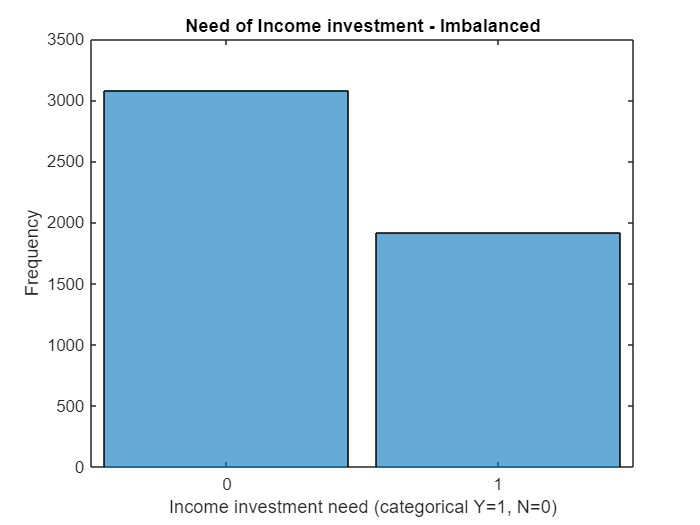

% Unbalanced class Income investement propensity
figure
histogram(Data.IncomeInvestment)
title('Need of Income investment - Imbalanced')
xlabel('Income investment need (categorical Y=1, N=0)')
ylabel('Frequency')

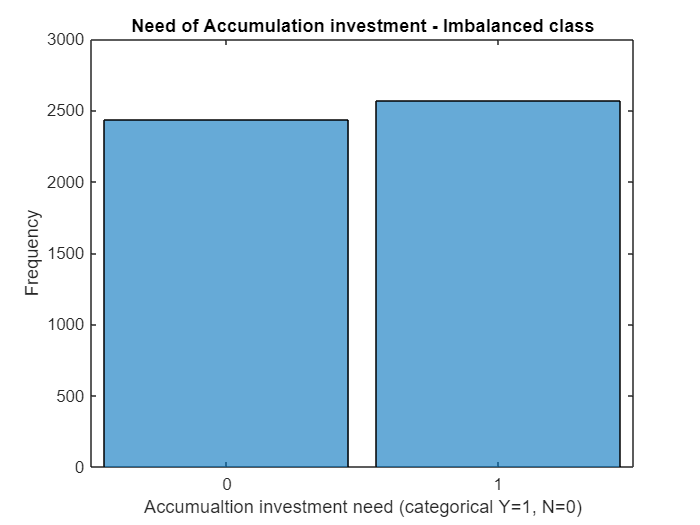

% Balanced class Accumulation investement propensity
figure
histogram(Data.AccumulationInvestment)
title('Need of Accumulation investment - Imbalanced class')
xlabel('Accumualtion investment need (categorical Y=1, N=0)')
ylabel('Frequency')

# (1) Classification Learner App

We look at the best classification models by training them on the Classification Learner App using k-fold Cross Validation with k=10.

We consider also that we would rather recommend a financial product to an uninterested client than the opposite. If we do not recognize a client as interested, that would represent a **missed opportunity for a profit**. Because of that we decide to raise the **misclassification cost** from 1 to 2.

--------------------------------------------------------------------------------------------------

For the Accumulation Need using K-fold Cross Validation we get an accuracy in the validation of:

- 71.6% for the Medium Tree

- 73.5% for RUSBoosted Tree

- 74.5% for the Boosted Trees

- 75.1% for Fine Tree

- 77.3% for Bagged Trees

Testing the model on the Classification Learn app we get an accuracy of:

- 74.1% for the Medium Tree

- 74.4% for RUSBoosted Tree

- 78.1% for the Boosted Trees

- 80.0% for Fine Tree

- 78.9% for Bagged Trees

--------------------------------------------------------------------------------------------------

For the Income Need using K-fold Cross Validation we get an accuracy in the validation of:

- 77.8% for the Medium Tree

- 79.3% for RUSBoosted Tree

- 79.2%% for the Boosted Trees

- 77.4% for Fine Tree

- 76.6% for Bagged Trees

Testing the model on the Classification Learn app we get an accuracy of:

- 78.1% for the Medium Tree

- 79.3% for RUSBoosted Tree

- 79.9% for the Boosted Trees

- 78.1% for Fine Tree

- 77.9% for Bagged Trees

## Roc Curves

We report below the accuracy and the plot of the ROC-curves of the best models selected by the Classification Learner App.

response = yInvAccTrain;
[trainedClassifierMT, validationAccuracyMT] = MediumTree(DataTrain, response);
validationAccuracyMT

validationAccuracyMT = 0.7280

[trainedClassifierBoosT, validationAccuracyBoosT] = BoostedTree(DataTrain, response);
validationAccuracyBoosT

validationAccuracyBoosT = 0.7430

[trainedClassifierBagT, validationAccuracyBagT] = BagTree(DataTrain, response);
validationAccuracyBagT

validationAccuracyBagT = 0.7700

[trainedClassifierRUSBoosT, validationAccuracyRUSBoosT] = RUSBoostedTree(DataTrain, response);
validationAccuracyRUSBoosT

validationAccuracyRUSBoosT = 0.7413

[trainedClassifierFT, validationAccuracyFT] = FineTree(DataTrain, response);
validationAccuracyFT

validationAccuracyFT = 0.7695

%Predicting the scores
[~,scoresMT] = trainedClassifierMT.predictFcn(DataTrain);
[~,scoresBoosT] = trainedClassifierBoosT.predictFcn(DataTrain);
[~,scoresRUSBoosT] = trainedClassifierRUSBoosT.predictFcn(DataTrain);
[~,scoresFT] = trainedClassifierFT.predictFcn(DataTrain);

%Coordinates for the ROC curve - area under the curve
[X_MT,Y_MT,~,AUC_MT] = perfcurve(response,scoresMT(:,2),1);
AUC_MT

AUC_MT = 0.8000

[X_BoosT,Y_BoosT,~,AUC_BoosT] = perfcurve(response,scoresBoosT(:,2),1);
AUC_BoosT

AUC_BoosT = 0.8913

[X_RUSBoosT,Y_RUSBoosT,~,AUC_RUSBoosT] = perfcurve(response,scoresRUSBoosT(:,2),1);
AUC_RUSBoosT

AUC_RUSBoosT = 0.8393

[X_FT,Y_FT,~,AUC_FT] = perfcurve(response,scoresFT(:,2),1);
AUC_FT

AUC_FT = 0.8957

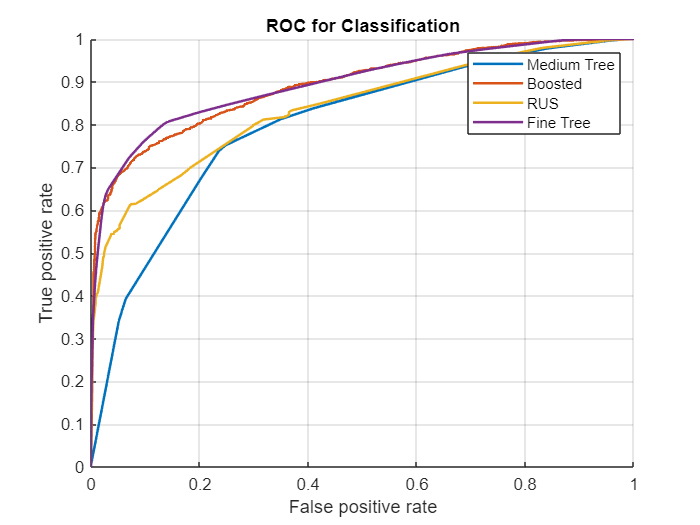

figure, hold on, grid on
plot(X_MT,Y_MT,'LineWidth',1.5)
plot(X_BoosT,Y_BoosT,'LineWidth',1.5)
plot(X_RUSBoosT,Y_RUSBoosT,'LineWidth',1.5)
plot(X_FT,Y_FT,'LineWidth',1.5)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification')
legend('Medium Tree','Boosted','RUS','Fine Tree')

Looking at the **AUC** **score** the best model is** Fine Tree.**

# (2) Different Models 

We try also to use different models **outside** of the Classification Learner App and we print their metrics in order to have a better look at their perfomances, to check it we use state of measure (function).

OptimisationSettings = struct("Holdout",0.175,"ShowPlots",false,"Verbose",0,"AcquisitionFunctionName",'expected-improvement-plus');
y_predicted_inc=[];
y_predicted_acc=[];

%% Single Tree 
% Income Investment
rng('default');

Model1_inc= fitctree(TrainTable,yInvIncTrain,"Reproducible",true,"OptimizeHyperparameters", ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings);

y_predicted_inc = [predict(Model1_inc,TestTable)];

Model_names = {'Single Tree'};
statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         548        246        397        397  
    "false_positive"        151         55        103        103  
    "false_negative"         55        151        103        103  
    "true_negative"         246        548        397        397  
    "precision"         0.78398    0.81728    0.80063      0.794  
    "sensitivity"       0.90879    0.61965    0.76422      0.794  
    "specificity"       0.61965    0.90879    0.76422      0.794  
    "accuracy"            0.794      0.794      0.794      0.794  
    "F-measure"         0.84178    0.70487    0.77333      0.794  


rng('default')

%% Single Tree
% 'AccumulationInvestment'

Model1_acc = fitctree(TrainTable,yInvAccTrain,"Reproducible",true,"OptimizeHyperparameters", ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings);

y_predicted_acc = [predict(Model1_acc,TestTable)];

Model_names = {'Single Tree'};
statsOfMeasure(confusionmat(yInvAccTest,y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         395        398      396.5      396.5  
    "false_positive"        139         68      103.5      103.5  
    "false_negative"         68        139      103.5      103.5  
    "true_negative"         398        395      396.5      396.5  
    "precision"          0.7397    0.85408    0.79689      0.793  
    "sensitivity"       0.85313    0.74115    0.79714      0.793  
    "specificity"       0.74115    0.85313    0.79714      0.793  
    "accuracy"            0.793      0.793      0.793      0.793  
    "F-measure"         0.79238    0.79362      0.793      0.793  


rng('default')

%%Single Tree(Modified Cost)
%Income Investment

Model2_inc = fitctree(TrainTable,yInvIncTrain,"Reproducible",true, ...
    "OptimizeHyperparameters",'auto',"HyperparameterOptimizationOptions", ...
    OptimisationSettings,"Cost",[0 1;2 0]);

y_predicted_inc = [y_predicted_inc predict(Model2_inc,TestTable)];

Model_names = [Model_names, {'Single Tree (Modified Cost)'}];
statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         527        254      390.5      390.5  
    "false_positive"        143         76      109.5      109.5  
    "false_negative"         76        143      109.5      109.5  
    "true_negative"         254        527      390.5      390.5  
    "precision"         0.78657     0.7697    0.77813      0.781  
    "sensitivity"       0.87396     0.6398    0.75688      0.781  
    "specificity"        0.6398    0.87396    0.75688      0.781  
    "accuracy"            0.781      0.781      0.781      0.781  
    "F-measure"         0.82797    0.69876    0.76336      0.781  


rng('default');

%Accumulation Investment
Model2_acc = fitctree(TrainTable,yInvAccTrain,"Reproducible",true, ...
    "OptimizeHyperparameters",'auto',"HyperparameterOptimizationOptions", ...
    OptimisationSettings,"Cost",[0 1;2 0]);

y_predicted_acc = [y_predicted_acc predict(Model2_acc,TestTable)];

Model_names = [Model_names, {'Single Tree (Modified Cost)'}];

statsOfMeasure(confusionmat(yInvAccTest,y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         335        433        384        384  
    "false_positive"        104        128        116        116  
    "false_negative"        128        104        116        116  
    "true_negative"         433        335        384        384  
    "precision"          0.7631    0.77184    0.76747      0.768  
    "sensitivity"       0.72354    0.80633    0.76494      0.768  
    "specificity"       0.80633    0.72354    0.76494      0.768  
    "accuracy"            0.768      0.768      0.768      0.768  
    "F-measure"         0.74279    0.78871    0.76575      0.768  


%Fitcensemble
%income investment

TreeBasis = templateTree('Reproducible',true);

Model3_inc = fitcensemble(TrainTable,yInvIncTrain,"OptimizeHyperparameters", ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Learners",TreeBasis);

rng('default');
y_predicted_inc = [y_predicted_inc predict(Model3_inc,TestTable)];

statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         564        244        404        404  
    "false_positive"        153         39         96         96  
    "false_negative"         39        153         96         96  
    "true_negative"         244        564        404        404  
    "precision"         0.78661    0.86219     0.8244      0.808  
    "sensitivity"       0.93532    0.61461    0.77497      0.808  
    "specificity"       0.61461    0.93532    0.77497      0.808  
    "accuracy"            0.808      0.808      0.808      0.808  
    "F-measure"         0.85455    0.71765     0.7861      0.808  


%Acc investment

Model3_acc = fitcensemble(TrainTable,yInvAccTrain,"OptimizeHyperparameters", ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Learners",TreeBasis);

rng('default');
y_predicted_acc = [y_predicted_acc predict(Model3_acc,TestTable)];

statsOfMeasure(confusionmat(yInvAccTest, y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         408        408        408        408  
    "false_positive"        129         55         92         92  
    "false_negative"         55        129         92         92  
    "true_negative"         408        408        408        408  
    "precision"         0.75978    0.88121    0.82049      0.816  
    "sensitivity"       0.88121    0.75978    0.82049      0.816  
    "specificity"       0.75978    0.88121    0.82049      0.816  
    "accuracy"            0.816      0.816      0.816      0.816  
    "F-measure"           0.816      0.816      0.816      0.816  


%Fitcensemble (Modified cost)
%Income Investment:

Model4_inc = fitcensemble(TrainTable,yInvIncTrain,"OptimizeHyperparameters", ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Learners", ...
    TreeBasis,"Cost",[0 1;2 0]);


y_predicted_inc = [y_predicted_inc predict(Model4_inc,TestTable)];

statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         550        243      396.5      396.5  
    "false_positive"        154         53      103.5      103.5  
    "false_negative"         53        154      103.5      103.5  
    "true_negative"         243        550      396.5      396.5  
    "precision"         0.78125    0.82095     0.8011      0.793  
    "sensitivity"       0.91211    0.61209     0.7621      0.793  
    "specificity"       0.61209    0.91211     0.7621      0.793  
    "accuracy"            0.793      0.793      0.793      0.793  
    "F-measure"         0.84162     0.7013    0.77146      0.793  


%Acc investment:
Model4_acc = fitcensemble(TrainTable,yInvAccTrain,"OptimizeHyperparameters", ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Learners", ...
    TreeBasis,"Cost",[0 1;2 0]);


y_predicted_acc = [y_predicted_acc predict(Model4_acc,TestTable)];

statsOfMeasure(confusionmat(yInvAccTest,y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         387        399        393        393  
    "false_positive"        138         76        107        107  
    "false_negative"         76        138        107        107  
    "true_negative"         399        387        393        393  
    "precision"         0.73714       0.84    0.78857      0.786  
    "sensitivity"       0.83585    0.74302    0.78943      0.786  
    "specificity"       0.74302    0.83585    0.78943      0.786  
    "accuracy"            0.786      0.786      0.786      0.786  
    "F-measure"          0.7834    0.78854    0.78597      0.786  


% Support Vector Machine (SVM)
%Income Investment:

rng('default');

Model5_inc= fitcsvm(TrainTable,yInvIncTrain,'OptimizeHyperparameters', ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings);

y_predicted_inc = [y_predicted_inc predict(Model5_inc,TestTable)];

statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         537        220      378.5      378.5  
    "false_positive"        177         66      121.5      121.5  
    "false_negative"         66        177      121.5      121.5  
    "true_negative"         220        537      378.5      378.5  
    "precision"          0.7521    0.76923    0.76067      0.757  
    "sensitivity"       0.89055    0.55416    0.72235      0.757  
    "specificity"       0.55416    0.89055    0.72235      0.757  
    "accuracy"            0.757      0.757      0.757      0.757  
    "F-measure"         0.81549    0.64422    0.72985      0.757  


%Acc investment:

rng('default');

Model5_acc= fitcsvm(TrainTable,yInvAccTrain,'OptimizeHyperparameters', ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings);

y_predicted_acc = [y_predicted_acc predict(Model5_acc,TestTable)];

statsOfMeasure(confusionmat(yInvAccTest,y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         294        375      334.5      334.5  
    "false_positive"        162        169      165.5      165.5  
    "false_negative"        169        162      165.5      165.5  
    "true_negative"         375        294      334.5      334.5  
    "precision"         0.64474    0.68934    0.66704      0.669  
    "sensitivity"       0.63499    0.69832    0.66666      0.669  
    "specificity"       0.69832    0.63499    0.66666      0.669  
    "accuracy"            0.669      0.669      0.669      0.669  
    "F-measure"         0.63983     0.6938    0.66681      0.669  


%SVM with different error weights
%Income Investment:
rng('default');

Model6_inc = fitcsvm(TrainTable,yInvIncTrain,'OptimizeHyperparameters', ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Cost",[0 1;2 0]);

y_predicted_inc = [y_predicted_inc predict(Model6_inc,TestTable)];

statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         471        248      359.5      359.5  
    "false_positive"        149        132      140.5      140.5  
    "false_negative"        132        149      140.5      140.5  
    "true_negative"         248        471      359.5      359.5  
    "precision"         0.75968    0.65263    0.70615      0.719  
    "sensitivity"       0.78109    0.62469    0.70289      0.719  
    "specificity"       0.62469    0.78109    0.70289      0.719  
    "accuracy"            0.719      0.719      0.719      0.719  
    "F-measure"         0.77024    0.63835    0.70429      0.719  


%Acc Investment:
rng('default');

Model6_acc = fitcsvm(TrainTable,yInvAccTrain,'OptimizeHyperparameters', ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Cost",[0 1;2 0]);

y_predicted_acc = [y_predicted_acc predict(Model6_acc,TestTable)];

statsOfMeasure(confusionmat(yInvAccTest,y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         358        172        265        265  
    "false_positive"        365        105        235        235  
    "false_negative"        105        365        235        235  
    "true_negative"         172        358        265        265  
    "precision"         0.49516    0.62094    0.55805       0.53  
    "sensitivity"       0.77322     0.3203    0.54676       0.53  
    "specificity"        0.3203    0.77322    0.54676       0.53  
    "accuracy"             0.53       0.53       0.53       0.53  
    "F-measure"         0.60371     0.4226    0.51316       0.53  


%SVM with different error weights and Gaussian Kernel
%Income Investment

Model7_inc = fitcsvm(TrainTable,yInvIncTrain,'OptimizeHyperparameters', ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Cost",[0 1;2 0], ...
    "KernelFunction",'gaussian');

y_predicted_inc = [y_predicted_inc predict(Model7_inc,TestTable)];

statsOfMeasure(confusionmat(yInvIncTest,y_predicted_inc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         503        259        381        381  
    "false_positive"        138        100        119        119  
    "false_negative"        100        138        119        119  
    "true_negative"         259        503        381        381  
    "precision"         0.78471    0.72145    0.75308      0.762  
    "sensitivity"       0.83416    0.65239    0.74328      0.762  
    "specificity"       0.65239    0.83416    0.74328      0.762  
    "accuracy"            0.762      0.762      0.762      0.762  
    "F-measure"         0.80868    0.68519    0.74693      0.762  


%Accumulation Investment:

Model7_acc = fitcsvm(TrainTable,yInvAccTrain,'OptimizeHyperparameters', ...
    'auto',"HyperparameterOptimizationOptions",OptimisationSettings,"Cost",[0 1;2 0], ...
    "KernelFunction",'gaussian');

y_predicted_acc = [y_predicted_acc predict(Model7_acc,TestTable)];

statsOfMeasure(confusionmat(yInvAccTest,y_predicted_acc(:,end)), 1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         296        439      367.5      367.5  
    "false_positive"         98        167      132.5      132.5  
    "false_negative"        167         98      132.5      132.5  
    "true_negative"         439        296      367.5      367.5  
    "precision"         0.75127    0.72442    0.73785      0.735  
    "sensitivity"       0.63931     0.8175    0.72841      0.735  
    "specificity"        0.8175    0.63931    0.72841      0.735  
    "accuracy"            0.735      0.735      0.735      0.735  
    "F-measure"         0.69078    0.76815    0.72947      0.735  


# `(3) Fitcensemble models `

We select different models found by the classification learner app and fit them using 'fitcensemble', The misclassification cost is the same used before and the cross-validation is the 10-fold validation.

As an example we train the Bagged Ensemble model considering just the  'AccumulationInvestment' as a response.

% -------------------------------------------------------- ACCUMULATION ------------------------------------------------------------------------
response = yInvAccTrain;
rng('default')
template = templateTree('MaxNumSplits', 3999);
classificationEnsemble = fitcensemble(...
    TrainTable, ...
    response, ...
    'Method', 'Bag', ...                      bagged tree
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),... 
    'Cost', [0 1; 2 0],...                    misclassification costs
    'KFold', 10,...                           10-fold validation
    'CrossVal','on')

classificationEnsemble =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Bag'
         PredictorNames: {'Age'  'Family'  'FinEdu'  'Income'  'Wealth'}
           ResponseName: 'Y'
        NumObservations: 4000
                  KFold: 10
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [100 100 100 100 100 100 100 100 100 100]
             ClassNames: [0    1]
         ScoreTransform: 'none'


  Properties, Methods


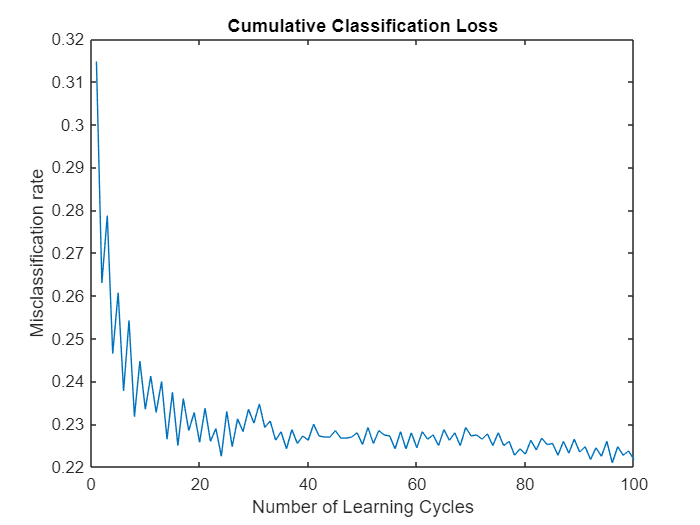

CVLoss = kfoldLoss(classificationEnsemble,'Mode','Cumulative');
figure;
plot(CVLoss);
xlabel('Number of Learning Cycles');
ylabel('Misclassification rate');
title('Cumulative Classification Loss')

estGenError = CVLoss(end)

estGenError = 0.2218

[labels, scores, cost] = kfoldPredict(classificationEnsemble);
tp = sum((labels == '1') & (response==1));
fp = sum((labels == '1') & (response ==0));
fn = sum((labels == '0') & (response ==1));
prec = tp / (tp + fp)

prec = 0.7805

rec = tp / (tp + fn)

rec = 0.7831

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7818

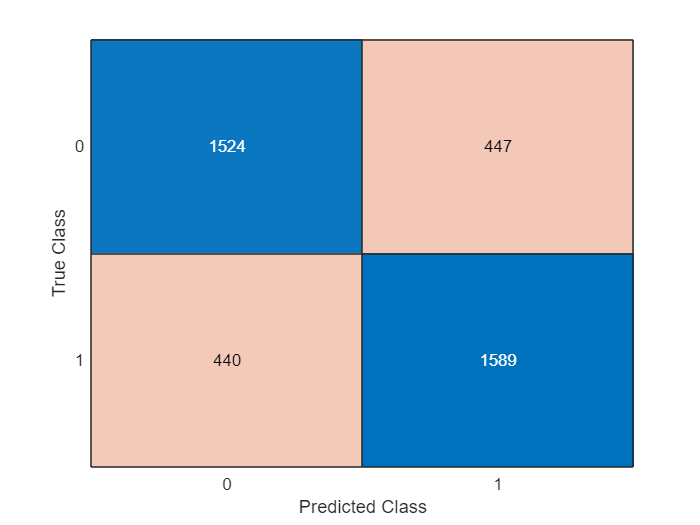

confusionchart(response, double(labels)-1)

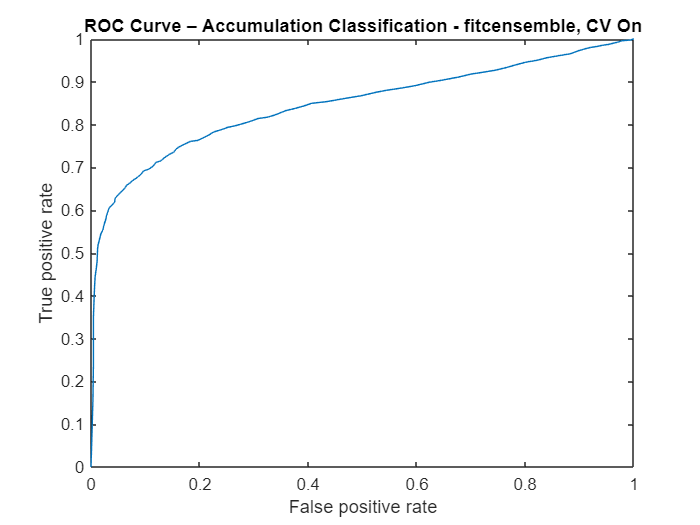

[X,Y,~,AUC] = perfcurve(response,scores(:,2),1);
figure
plot(X,Y)
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve – Accumulation Classification - fitcensemble, CV On')

AUC

AUC = 0.8465

### **Cross Validation Off**

Now that we have chosen the most performing model, we recreate it training the ensemble again, but now setting the **cross-validation off.**

classificationEnsemble = fitcensemble(...
    TrainTable, ...
    response, ...
    'Method', 'Bag', ...
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}),...
    'Cost', [0 1; 2 0],...
    'CrossVal','off')

classificationEnsemble =   ClassificationBaggedEnsemble
           PredictorNames: {'Age'  'Family'  'FinEdu'  'Income'  'Wealth'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 4000
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
                FResample: 1
                  Replace: 1
         UseObsForLearner: [4000×100 logical]


  Properties, Methods


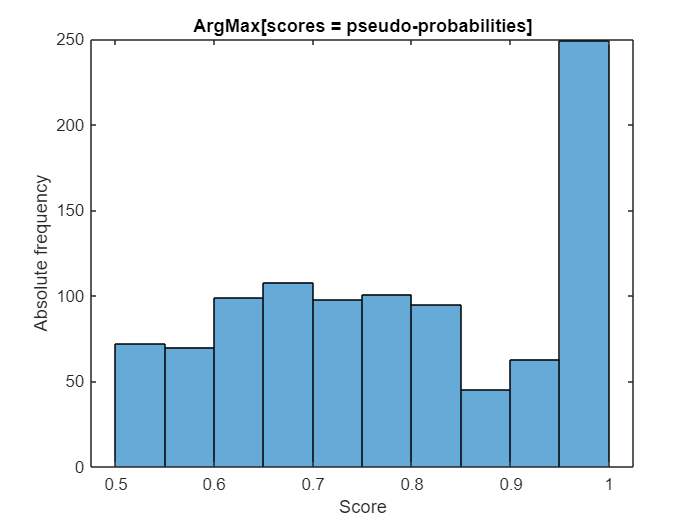

[labels,scores] = predict(classificationEnsemble,TestTable);
figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

tp = sum((labels == '1') & (yInvAccTest==1));
fp = sum((labels == '1') & (yInvAccTest==0));
fn = sum((labels == '0') & (yInvAccTest==1));
prec = tp / (tp + fp)

prec = 0.8083

rec = tp / (tp + fn)

rec = 0.8007

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.8045

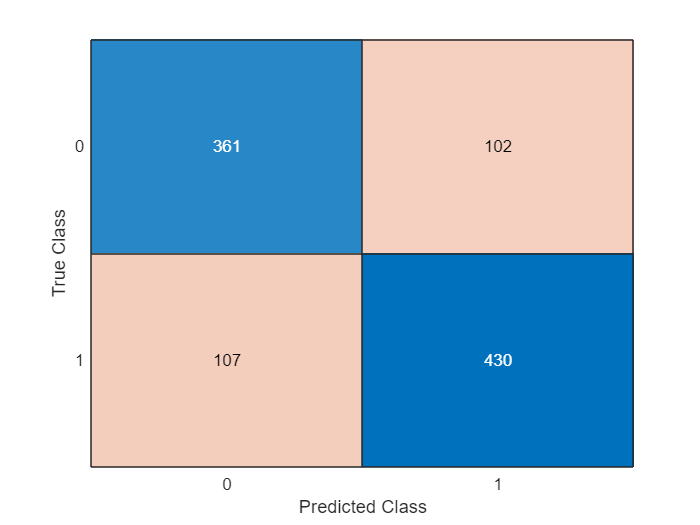

confusionchart(yInvAccTest, double(labels)-1)

# (3.1) Fit ensemble optimized 

We train the final models by hyperparameter optimization. 

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.28425 |      1.6375 |     0.28425 |     0.28425 |   AdaBoostM1 |           23 |      0.86397 |            2 |
|    2 | Best   |     0.22675 |      17.979 |     0.22675 |     0.22904 |          Bag |          214 |            - |            2 |
|    3 | Accept |       0.303 |       17.35 |     0.22675 |     0.23189 |          Bag |          340 |            - |           91 |
|    4 | Accept |     0.31725 |      7.2539 |     0.22675 |   

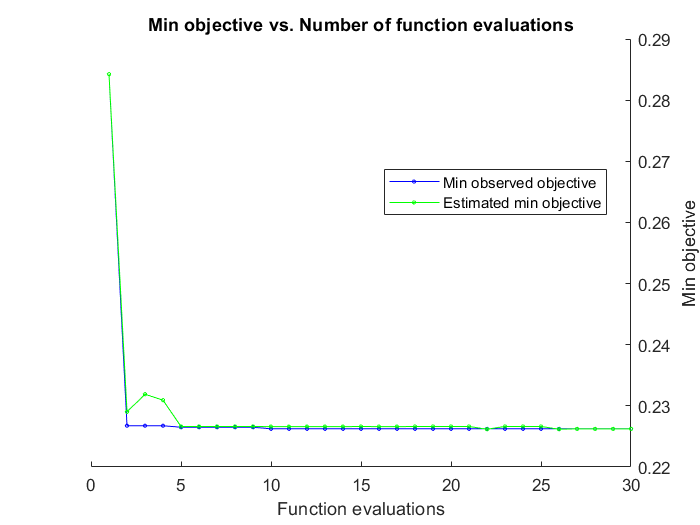


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 296.391 seconds
Total objective function evaluation time: 274.6399

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             485              NaN            3     

Observed objective function value = 0.22625
Estimated objective function value = 0.22624
Function evaluation time = 38.1245

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MDLTA =   ClassificationBaggedEnsemble
                       PredictorNames: {'Age'  'Family'  'FinEdu'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 4000
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 485
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: [4000×485 logical]


  <a href="matla

rng('default')          % setting seed for reproducibility
% ------------------------ Accumulation Investment - Classification -------------------------------------
t = templateTree('Reproducible',true);
MDLTA= fitcensemble(TrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'),'Cost', [0 1; 2 0])

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.21625 |        14.9 |     0.21625 |     0.21625 |          Bag |          187 |            - |            5 |
|    2 | Accept |       0.246 |      7.7367 |     0.21625 |     0.21743 |   AdaBoostM1 |          182 |      0.45904 |          322 |
|    3 | Accept |     0.61975 |      7.6553 |     0.21625 |     0.22713 |   AdaBoostM1 |          292 |    0.0015353 |         1837 |
|    4 | Best   |       0.212 |      1.3532 |       0.212 |   

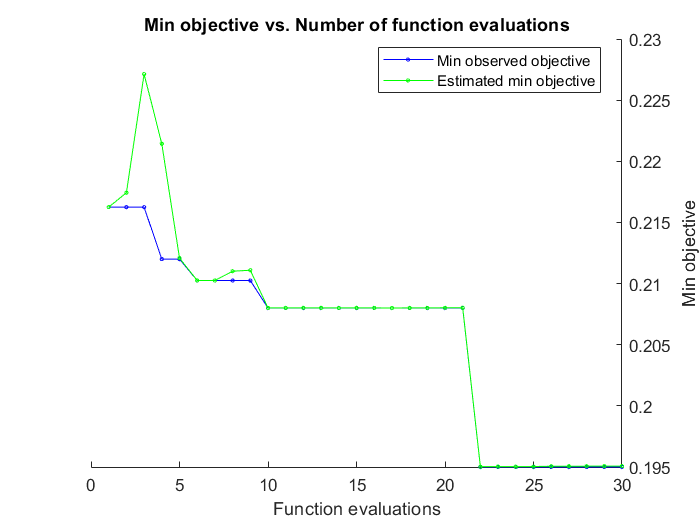


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 199.0378 seconds
Total objective function evaluation time: 182.4421

Best observed feasible point:
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________    ___________

    LogitBoost           165           0.049064         103    

Observed objective function value = 0.195
Estimated objective function value = 0.19507
Function evaluation time = 7.3198

Best estimated feasible point (according to models):
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________

MDLTI =   ClassificationEnsemble
                       PredictorNames: {'Age'  'Family'  'FinEdu'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 4000
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 165
                               Method: 'LogitBoost'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [165×1 double]
                   FitInfoDescription: {2×1 cell}


  Properties, 

% ------------------------ Income Investment - Classification -------------------------------------
MDLTI=fitcensemble(TrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'),'Cost', [0 1; 2 0])

# **Testing**

We now do some predictions on the test set.

[labels_a,scores_a] = predict(MDLTA,TestTable);
tp = sum((labels_a == 1) & (yInvAccTest==1));
fp = sum((labels_a == 1) & (yInvAccTest==0));
fn = sum((labels_a == 0) & (yInvAccTest==1));
prec = tp / (tp + fp)

prec = 0.8165

rec = tp / (tp + fn)

rec = 0.8119

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.8142

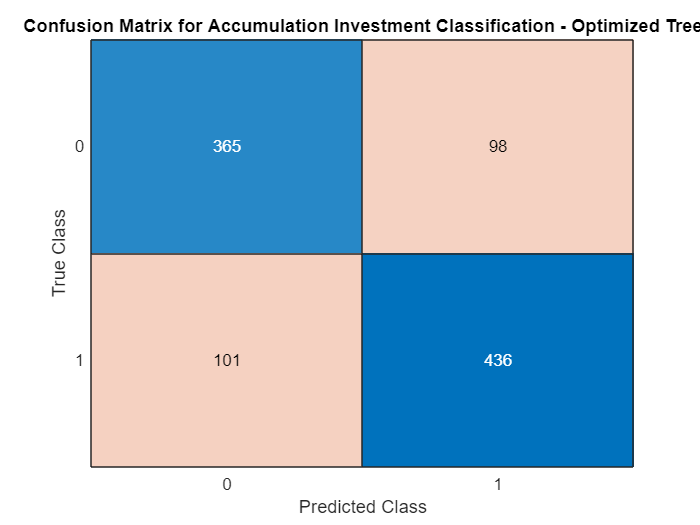

figure
confusionchart(yInvAccTest, double(labels_a))
title('Confusion Matrix for Accumulation Investment Classification - Optimized Tree')

[labels_i,scores_i] = predict(MDLTI, TestTable);
tp = sum((labels_i == 1) & (yInvIncTest == 1));
fp = sum((labels_i == 1) & (yInvIncTest == 0));
fn = sum((labels_i == 0) & (yInvIncTest == 1));
prec = tp / (tp + fp)

prec = 0.8582

rec = tp / (tp + fn)

rec = 0.6096

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7128

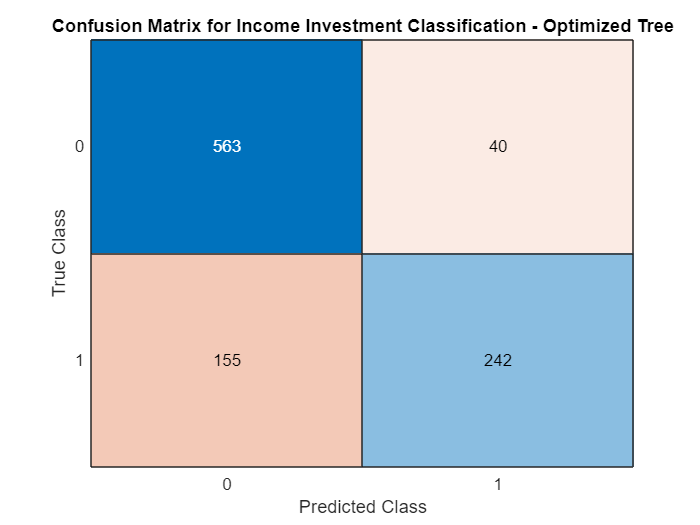

figure
confusionchart(yInvIncTest, double(labels_i))
title('Confusion Matrix for Income Investment Classification - Optimized Tree')

# Final considerations

After looking at the obtained perfomances from the above models, we decide to select **Ensemble Tree **(bagged) as the best model for the variable Accumualtion Investment. For the variable Income Investment we select **Logistic Regression **(look at the R code).